Входные параметры

close all;
clear variables;
tic; % замер времени

Входные параметры

% global N as dx

k = 2*pi; % волновое число, при лямде = 1
as = 11; % ширина ленты
N = 100; % количество точек коллокации
phi_grad = 45; % угол падения волны [град]
dx = as/N; % растояние между центрами цилиндров
eta = 120*pi;

Замена переменных

Новые константы

kdx = k*dx;
gamma = 1.781072417990;
kd4 = kdx/4;
% dx2 = dx/2;
delta = dx/2;
kd6 = kdx/6;

D0 = k*dx*(1+(1i*2/pi)*(log(gamma*kd4)-1));   

Генерация точек

Расчет кооодинат центров отрезков разбиения (без функции)

% генератора координат для первого участка
for n=1:N
    x1(n) = (n-0.5)*dx;
    z1(n) = 0;
    x2(n) = as;
    z2(n) = (n-0.5)*dx;
    x3(n) = (n-0.5)*dx;
    z3(n) = as;
    x4(n) = 0;
    z4(n) = (n-0.5)*dx;  
end

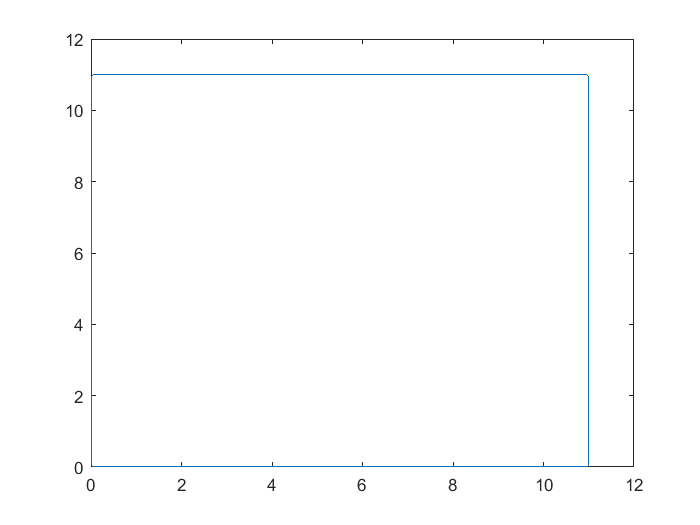

% координта на поверхности цилиндра
X = [x1 x2 fliplr(x3) x4];
Z = [z1 z2 z3 fliplr(z4)];

plot(X,Z)

Расчет касательных к отрезкам разибения

% касательные * до копирования
tx_one = [-1 0 1 0];
tz_one = [0 -1 0 1];


%  общие касательный
tz = [repmat(tz_one(1),1,N) repmat(tz_one(2),1,N) repmat(tz_one(3),1,N) repmat(tz_one(4),1,N)];
tx = [repmat(tx_one(1),1,N) repmat(tx_one(2),1,N) repmat(tx_one(3),1,N) repmat(tx_one(4),1,N)];

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    a = -90;
    matrix = [cosd(a),-sind(a); sind(a),cosd(a)];

for i = 1 : 4*N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Падающее поле

for m=1:4*N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % Определим координаты
    xm = X(m);
    zm = Z(m);
    txm = tx(m);
    tzm = tz(m);
    
%   Итоговое падающее поле
    Hi(m,1) = -exp(cx*xm+cz*zm); 
      
%   Итоговое падающее поел - это суперпозиция полей
    Eix = +eta*1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
    Eiz = -eta*1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
    Ei(m,1) = Eix*txm + Eiz*tzm;    
end


Падающее поле

% % излучаель создает магнитное поле 
% Ei = zeros(4*N,1);
% Hi = zeros(4*N,1);
% % падающее поле 
% x1_antenn = as+1/2;
% z1_antenn = as/2;
% 
% % падающее поле 
% for m = 1 : 4*N
%     xm = X(m);
%     zm = Z(m);
%     txm = tx(m);
%     tzm = tz(m);
%     
%     % растояния 
%     r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
%     
%     % Падающее магнитное поле
%     Hi(m) = besselh(0,1,k*r1);
%     % Падающее электрическое поле
%     Ex = +1i*eta*(zm-z1_antenn)*besselh(1,1,k*r1)/r1;
%      
%     Ez = -1i*eta*(xm-x1_antenn)*besselh(1,1,k*r1)/r1;
%     % Касательное электрическое поле
%     Ei(m) = Ex*txm + Ez*tzm;
% end  

## MFIE

Изучим один цикл


count = 0;
for m = 1 : 4*N
    
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = X(m);
    zm = Z(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : 4*N
    %   Координаты в исходной системе координат (в ГСК)
        xn = X(n);
        zn = Z(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);

    %   Центр новой системы кооридны - начало отрезка (в ГСК)

Давай возьмем середину отрезка

        x_begin_O2 = xn;
        z_begin_O2 = zn;
        
    %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
        x_mO2 = xm - x_begin_O2;
        z_mO2 =  zm - z_begin_O2;
         
%       Положим этот вектор на новую СК
%       Координаты этой точки (в ЛСК)
        xmO2 = x_mO2*txn + z_mO2*tzn;
        zmO2 = x_mO2*nxn + z_mO2*nzn;
           

Т.к. взяли на начало середину отрезка то тут будет

        % координаты в локальных координатах
        umn = xmO2;
        wmn = zmO2;

%       Растояние между m и n (в ГСК)
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
%       Расчет матричных элементов (в ЛСК)
        
        Hus = 0;
        Hws = 0;
        if n == m %r < 0.001*dx 
            
            % y - cоставляющая 
            Hys = -0.5;
            
        elseif abs(n - m) < 1.5 %r <= 2*dx
            % y - cоставляющая                     
            umn_plus_dx2 = umn + dx/2;
            umn_minus_dx2 = umn - dx/2;
            Hys = -(1i/8*wmn*k^2*dx + 1/(2*pi)*(atan(umn_plus_dx2/wmn) - atan(umn_minus_dx2/wmn)));
                 
        else 
            % y - cоставляющая
            rmn = sqrt(umn^2 + wmn^2);    
            Hys = -1i/4*k*dx*(wmn/rmn*besselh(1,1,k*rmn));  
            
        end
        
%       символ кронкера
        if m == n
            kronker = 1;
        else 
            kronker = 0;
        end
        
        % расчет матричнх элементов 
        Zmn_MFIE(m,n) = kronker + Hys;

    end
end

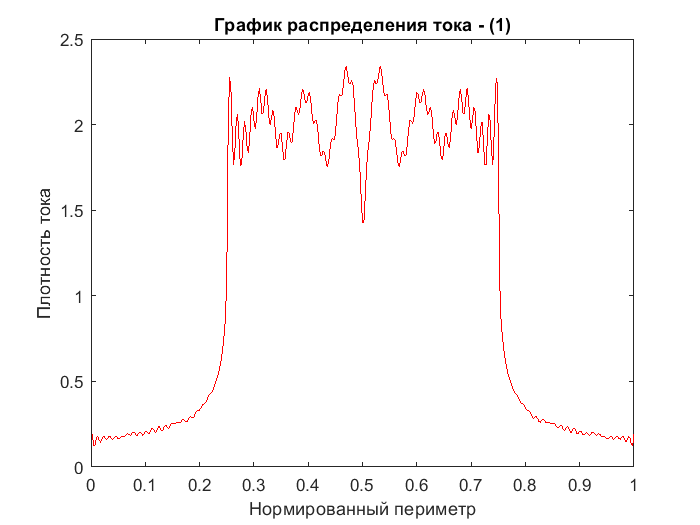

% расчеток токов ВИ 
I_MFIE=Zmn_MFIE\Hi;

% ось X в относительных единицах
figure;
plot((1:4*N)/(4*N), abs(I_MFIE), 'r');
title('График распределения тока - (1)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');

## EFIE

for m = 1 : 4*N
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = X(m);
    zm = Z(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : 4*N
    %   Координаты в исходной системе координат (в ГСК)
        xn = X(n);
        zn = Z(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
    %         dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
%       Расчет матричных элементов (в ЛСК)  
        if n == m 
            % cоставляющие E1u
            fe_u12 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k*dx/4)-1)); 
        elseif abs(n-m) <= 1.5 
            hm_y1 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k/2*sqrt(umn_minus^2+wmn^2)) - dx);
            hm_y1 = hm_y1 * 1i/4; % домножение на коэфицент
            fe_u12 = hm_y1;
        else 
            % cоставляющие E1u
            fe_u12 = 1i/4*dx*besselh(0,1,k*rmn);
        end
        % cоставляющие E1u
        fe_u11 = - 1i/4*k*(umn_plus/r_plus*besselh(1,1,k*r_plus) - umn_minus/r_minus*besselh(1,1,k*r_minus));
        % cоставляющие E1w
        fe_w1 = - 1i/4*k*(wmn/r_plus*besselh(1,1,k*r_plus) - wmn/r_minus*besselh(1,1,k*r_minus));
        
        %% СОБЕРЕМ ВСЕ ВМЕСТЕ
        E1u = 1i*eta/k*(fe_u11 + k^2*fe_u12);
        E1w = 1i*eta/k*fe_w1;
        
        dot_tm_tn = (txm*txn+tzm*tzn);
        dot_tm_nn = (txm*nxn+tzm*nzn);
        Zmn_EFIE(m,n) = dot_tm_tn*E1u + dot_tm_nn*E1w;    
        
%     %   Центр новой системы кооридны - середина отрезка (в ГСК)

Давай возьмем середину отрезка

%         x_begin_O2 = xn;
%         z_begin_O2 = zn;
%         
%     %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
%         x_mO2 = xm - x_begin_O2;
%         z_mO2 =  zm - z_begin_O2;
%          
% %       Положим этот вектор на новую СК
% %       Координаты этой точки (в ЛСК)
%         xmO2 = x_mO2*txn + z_mO2*tzn;
%         zmO2 = x_mO2*nxn + z_mO2*nzn;
%         
%     %   Растояние от n до точки m (в ЛСК)  

Т.к. взяли на начало середину отрезка то тут будет

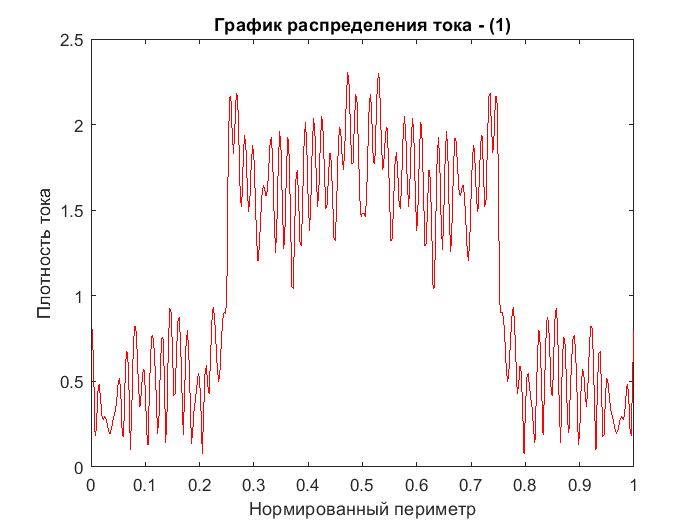

%         xmnO2 = xmO2;
%         zmnO2 = zmO2; 
% 
% %       Растояние между m и n (в ГСК)
%         xmn = xm - xn;
%         zmn = zm - zn;
%         r = sqrt(xmn^2 + zmn^2);
        
% 
%         if r < 0.001*dx
%             Zm = D0;
%    
%         elseif r <= dx 
% %             k_xm_plus = k*(abs(xmnO2)+delta);
% %             k_xm_minus = k*(abs(xmnO2)-delta);
% %             Zm = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
% %             
%             xmn_plus_delta = (xmnO2) + delta;
%             xmn_minus_delta = (xmnO2) - delta;
%             r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
%             r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
% %             zmn = abs(zmnO2);
% %             Zm = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(asin(xmn_plus_delta/r_plus_delta)- asin(xmn_minus_delta/r_minus_delta)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
%             zmn = zmnO2;
%             Zm = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
% 
%         else
%             f2 = besselh(0,1,k*r);
%             Zm = k*dx*f2;
%         end
%         
%         r_x_plus = sqrt((xmnO2+delta)^2+zmnO2^2);
%         r_x_minus = sqrt((xmnO2-delta)^2+zmnO2^2);
%         
%         Esx= (xmnO2-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmnO2+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Zm;
%         Esz = (zmnO2)/r_x_minus*besselh(1, 1, k*r_x_minus) - (zmnO2)/r_x_plus*besselh(1, 1, k*r_x_plus);        
% 
%          tx_betven_vectors = txm*txn + tzm*tzn;
%         tz_betven_vectors = txm*nxn + tzm*nzn;
%         
%         Zmn_EFIE(m,n) = Esx*tx_betven_vectors + Esz*tz_betven_vectors;
            
    end 
end

% расчеток токов ВИ 
I_EFIE=Zmn_EFIE\Ei;

% ось X в относительных единицах
figure;
plot((1:4*N)/(4*N), abs(I_EFIE), 'r');
title('График распределения тока - (1)'); 
xlabel('Нормированный периметр'); 
ylabel('Плотность тока');

#### CFIE

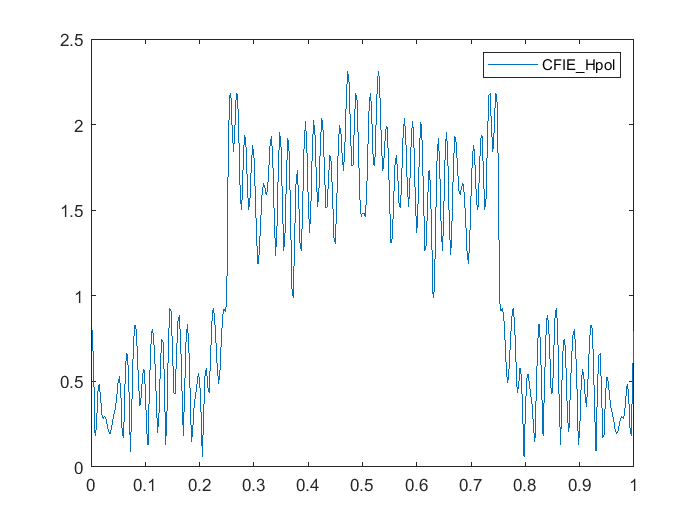

alpha = 0.5;
Hpol_CFIE_Zmn = alpha*Zmn_EFIE + (1-alpha)*Zmn_MFIE;
Hpol_CFIE_Ei = alpha*Ei + (1-alpha)*Hi;

Hpol_CFIE_I = Hpol_CFIE_Zmn\Hpol_CFIE_Ei;

plot((1:4*N)/(4*N), abs(Hpol_CFIE_I))
legend('CFIE\_Hpol')